# Debevec Algorithm

## Plot response curve for exposure times $j = 15$ and pixel points $i=5$

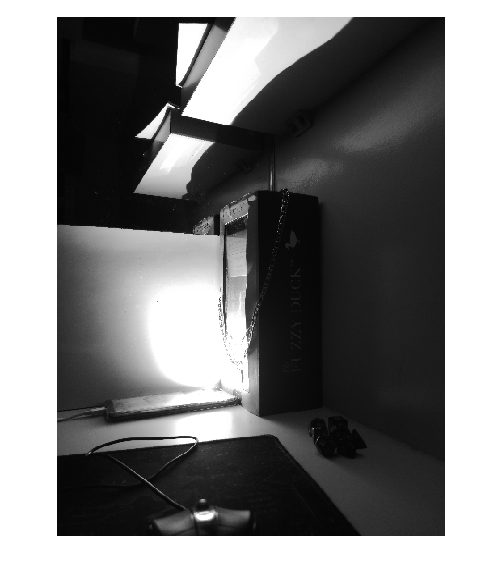

% Load Images
I2{1} = rgb2gray(imread('01-s4.jpg'));
I2{2} = rgb2gray(imread('02-s2.jpg'));
I2{3} = rgb2gray(imread('03-s1.jpg'));
I2{4} = rgb2gray(imread('s1-2.jpg'));
I2{5} = rgb2gray(imread('s1-4.jpg'));
I2{6} = rgb2gray(imread('s1-8.jpg'));
I2{7} = rgb2gray(imread('s1-15.jpg'));
I2{8} = rgb2gray(imread('s1-30.jpg'));
I2{9} = rgb2gray(imread('s1-60.jpg'));
I2{10} = rgb2gray(imread('s1-125.jpg'));
I2{11} = rgb2gray(imread('s1-250.jpg'));
I2{12} = rgb2gray(imread('s1-500.jpg'));
I2{13} = rgb2gray(imread('s1-1000.jpg'));
I2{14} = rgb2gray(imread('s1-2000.jpg'));
I2{15} = rgb2gray(imread('s1-4000.jpg'));

figure(1);
imshow(I2{6});

imwrite(I2{6},'gray6.jpg');

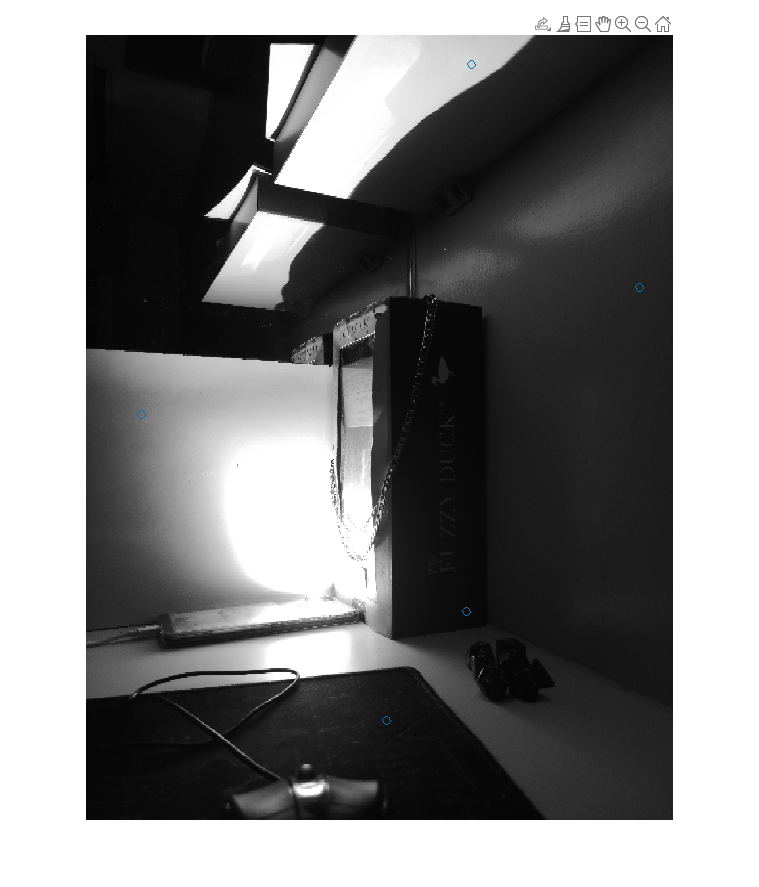

% Chosen 5 pixel points
% locsx=[1300,2269,2233,1370,406];
% locsy=[3202,1658,3480,3415,4272];

% Manual Choice
figure(2);
imshow(I2{6})
hold on
[locsx, locsy] = ginput(5);
locsx = round(locsx);
locsy = round(locsy);
scatter(locsx,locsy,"o");
hold off

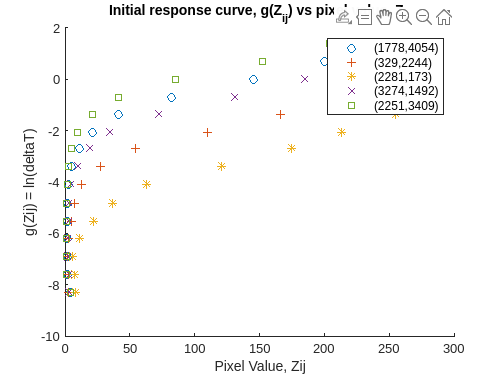


% Set exposure times
deltaT  = [4;2;1;1/2;1/4;1/8;1/15;1/30;1/60;1/125;1/250;1/500;1/1000;1/2000;1/4000];
logDeltaT = log(deltaT);

% Setup variables
Z = zeros(numel(locsx),size(I2,2));
ni = numel(locsx);                      % number of pixel points, i
nj = size(I2,2);                        % number of exposure images, j
markers = ["o","+","*","x","square"];

% Obtain Zij for 5 points
for i=1:ni                    % iterate over pixel points 
    pixVals = zeros(nj,1);
    exposures = zeros(nj,1);
    ix = locsx(i);
    iy = locsy(i);
    for j=1:nj                  % iterate over exposures
        Z(i,j) = I2{j}(iy,ix);
        pixVals(j) = I2{j}(iy,ix);
        exposures(j) = logDeltaT(j);
    end
    figure(3);
    scatter(pixVals,exposures,markers(i),'DisplayName', ...
            sprintf('(%d,%d)',ix,iy))
    hold on
end
title('Initial response curve, g(Z_{ij}) vs pixel value, Z_{ij}')
xlabel('Pixel Value, Zij')
ylabel('g(Zij) = ln(deltaT)')
legend()
hold off

## Solve for response function $g(Z_{ij})$

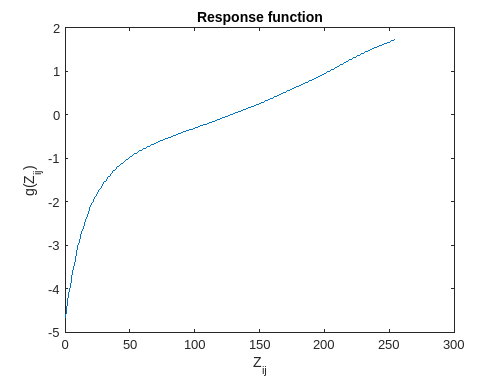

% Initialize weighing function
weight = zeros(256,1);
for i=1:256
    if i<=0.5*257
      weight(i) = i - 1;
    else
      weight(i) = 256 - i;
    end
end

% Initialize smoothing parameter
lambda = 50;

% Restructure logDeltaT for the g solver
logDeltaT1 = zeros(ni*nj,nj);
for j=1:nj
    logDeltaT1(:,j) = logDeltaT(j);
end

% Solve for the optimized g
[g, lE] = gMinimize(Z,logDeltaT1,lambda,weight);

% Plot response function
figure(4);
plot((0:255),g)
title('Response function')
xlabel('Z_{ij}')
ylabel('g(Z_{ij})')

## Compute HDR Radiance Map


$$\ln{E_i} = \frac{ \sum^P_{j=1} w(Z_{ij}) (g(Z_{ij}) - \ln\Delta t_j) }{ \sum^P_{j=1} w(Z_{ij}) }$$$


hdr = zeros(size(I2{1}));
sum = zeros(size(I2{1}));
for j=1:nj
    fprintf('Processing image %i of %i \n', j, nj);
    im = I2{j};                                % Current image exposure
    wij = weight(im+1);                        % Calculate weights
    sum = sum + wij;                           % Add sum of weights
    numerator = g(im+1) - logDeltaT(j);        % Calculate summand
    hdr = hdr + (numerator.*wij);
end

Processing image 1 of 15 
Processing image 2 of 15 
Processing image 3 of 15 
Processing image 4 of 15 
Processing image 5 of 15 
Processing image 6 of 15 
Processing image 7 of 15 
Processing image 8 of 15 
Processing image 9 of 15 
Processing image 10 of 15 
Processing image 11 of 15 
Processing image 12 of 15 
Processing image 13 of 15 
Processing image 14 of 15 
Processing image 15 of 15 


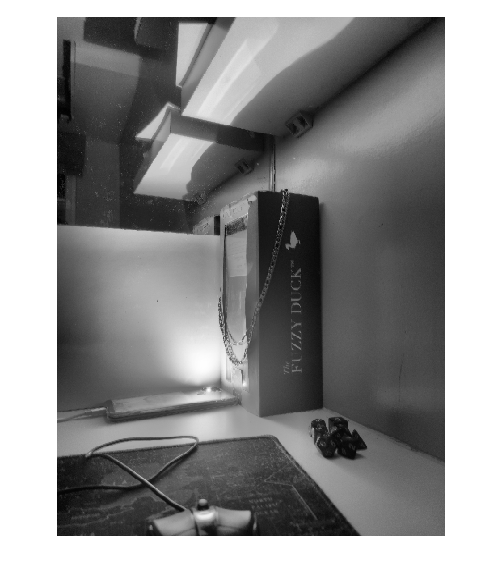


lnE = hdr./sum;
hdr = exp(lnE);
mono = tonemap(hdr);
imshow(mono)

imwrite(mono,'hdr-image.jpg');

## Obtain aligned response function from sample points

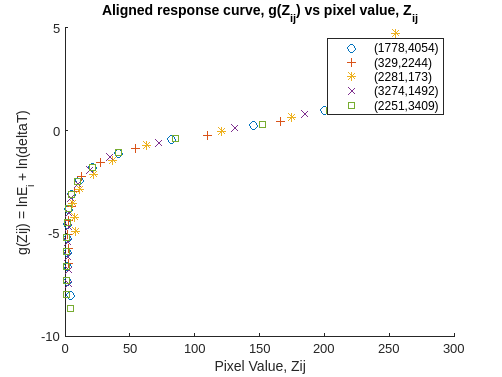

% Obtain Zij for 5 points
for i=1:ni                    % iterate over pixel points 
    pixVals = zeros(nj,1);
    exposures = zeros(nj,1);
    ix = locsx(i);
    iy = locsy(i);
    for j=1:nj                  % iterate over exposures
        Z(i,j) = I2{j}(iy,ix);
        pixVals(j) = I2{j}(iy,ix);
        exposures(j) = logDeltaT(j) + lnE(iy,ix);
    end
    figure(5);
    scatter(pixVals,exposures,markers(i),'DisplayName', ...
            sprintf('(%d,%d)',ix,iy))
    hold on
end
title('Aligned response curve, g(Z_{ij}) vs pixel value, Z_{ij}')
xlabel('Pixel Value, Zij')
ylabel('g(Zij) = lnE_i + ln(deltaT)')
legend()
hold off

# Following the number of measurement criterion


$$N > \frac{(Z_{max} - Z_{min}) }{(P-1)} > \frac{255}{P-1} > \frac{255}{14} > 19$$
 

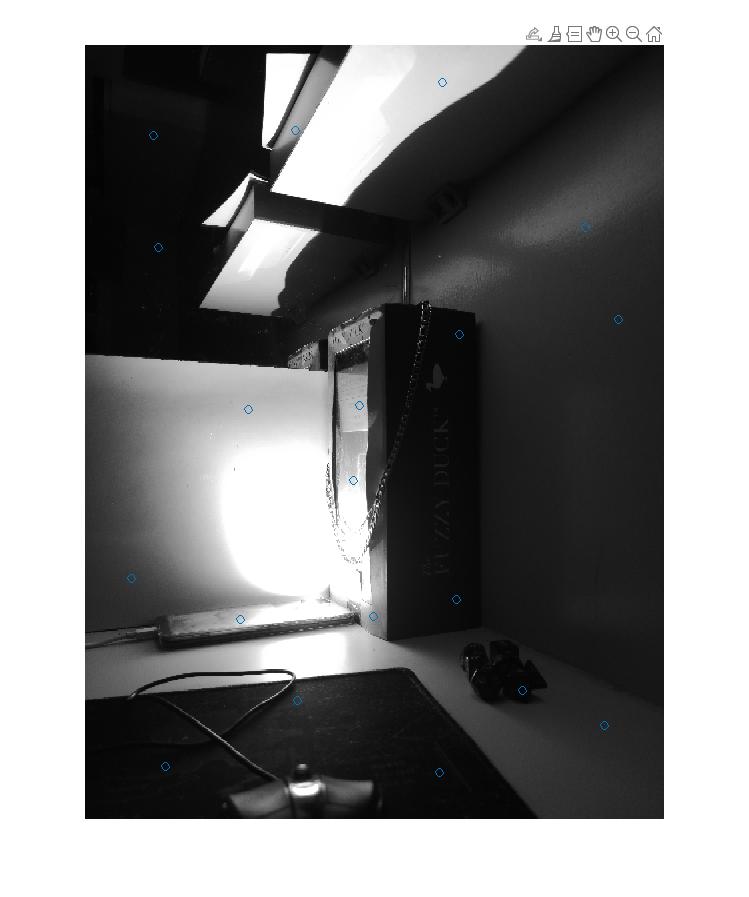

% Manual Choice
figure(2);
imshow(I2{6})
hold on
[locsx, locsy] = ginput(19);
locsx = round(locsx);
locsy = round(locsy);
scatter(locsx,locsy,"o");
hold off

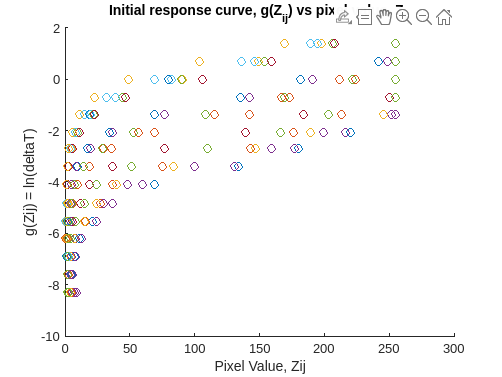


% Set exposure times
deltaT  = [4;2;1;1/2;1/4;1/8;1/15;1/30;1/60;1/125;1/250;1/500;1/1000;1/2000;1/4000];
logDeltaT = log(deltaT);

% Setup variables
Z = zeros(numel(locsx),size(I2,2));
ni = numel(locsx);                      % number of pixel points, i
nj = size(I2,2);                        % number of exposure images, j
% markers = ["o","+","*","x","square"];

% Obtain Zij for 5 points
for i=1:ni                    % iterate over pixel points 
    pixVals = zeros(nj,1);
    exposures = zeros(nj,1);
    ix = locsx(i);
    iy = locsy(i);
    for j=1:nj                  % iterate over exposures
        Z(i,j) = I2{j}(iy,ix);
        pixVals(j) = I2{j}(iy,ix);
        exposures(j) = logDeltaT(j);
    end
    figure(3);
    scatter(pixVals,exposures,"o")
    hold on
end
title('Initial response curve, g(Z_{ij}) vs pixel value, Z_{ij}')
xlabel('Pixel Value, Zij')
ylabel('g(Zij) = ln(deltaT)')
hold off

hdr = zeros(size(I2{1}));
sum = zeros(size(I2{1}));
for j=1:nj
    fprintf('Processing image %i of %i \n', j, nj);
    im = I2{j};                                % Current image exposure
    wij = weight(im+1);                        % Calculate weights
    sum = sum + wij;                           % Add sum of weights
    numerator = g(im+1) - logDeltaT(j);        % Calculate summand
    hdr = hdr + (numerator.*wij);
end

Processing image 1 of 15 
Processing image 2 of 15 
Processing image 3 of 15 
Processing image 4 of 15 
Processing image 5 of 15 
Processing image 6 of 15 
Processing image 7 of 15 
Processing image 8 of 15 
Processing image 9 of 15 
Processing image 10 of 15 
Processing image 11 of 15 
Processing image 12 of 15 
Processing image 13 of 15 
Processing image 14 of 15 
Processing image 15 of 15 



lnE = hdr./sum;
hdr = exp(lnE);
mono = tonemap(hdr);
imshow(mono)

imwrite(mono,'hdr-image-19.jpg');

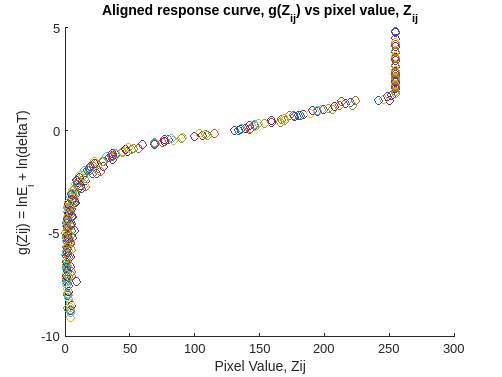

% Obtain Zij for 19 points
for i=1:ni                    % iterate over pixel points 
    pixVals = zeros(nj,1);
    exposures = zeros(nj,1);
    ix = locsx(i);
    iy = locsy(i);
    for j=1:nj                  % iterate over exposures
        Z(i,j) = I2{j}(iy,ix);
        pixVals(j) = I2{j}(iy,ix);
        exposures(j) = logDeltaT(j) + lnE(iy,ix);
    end
    figure(5);
    scatter(pixVals,exposures,"o")
    hold on
end
title('Aligned response curve, g(Z_{ij}) vs pixel value, Z_{ij}')
xlabel('Pixel Value, Zij')
ylabel('g(Zij) = lnE_i + ln(deltaT)')
hold off

function [g,lE]=gMinimize(Z,logDeltaT1,lamda,weight)
    % Arguments: 
    % 
    % Z(i,j) is the pixel values of pixel location number i in image j 
    % logDeltaT1(j) is the log delta t, or log shutter speed, for image j 
    % lambda is lamdba, the constant that determines the amount of smoothness 
    % weight(z) is the weighting function value for pixel value z 
    % 
    % Returns: 
    % 
    % g(z) is the log exposure corresponding to pixel value z 
    % lE(i) is the log film irradiance at pixel location i
    
    n = 256;
    G = zeros(size(Z,1)*size(Z,2)+n+1,n+size(Z,1));
    b = zeros(size(G,1),1);
    start = 1;
    for i=1:size(Z,1)
        for j=1:size(Z,2)
            wij = weight(Z(i,j)+1);
            G(start,Z(i,j)+1) = wij;
            G(start,n+i) = -wij;
            b(start,1) = wij * logDeltaT1(i,j);
            start=start+1;  
        end
    end
    G(start,129) = 1;
    start=start+1;
    for i=1:n-2
        % g''(z)= g(z-1) - 2g(z) + g(z+1)
        G(start,i)=lamda*weight(i+1); 
        G(start,i+1)=-2*lamda*weight(i+1);
        G(start,i+2)=lamda*weight(i+1);
        start=start+1;
    end
    x = G\b;
    g = x(1:n);
    lE = 0;
    % lE = x(n+1,size(x,1));
end